# Summary Results Demo

In this demo Live Scripts analyze the cost desaggregatio in terms of natural resources using the `SummaryResults `functionality, applying to a recycling plant of PCB's 

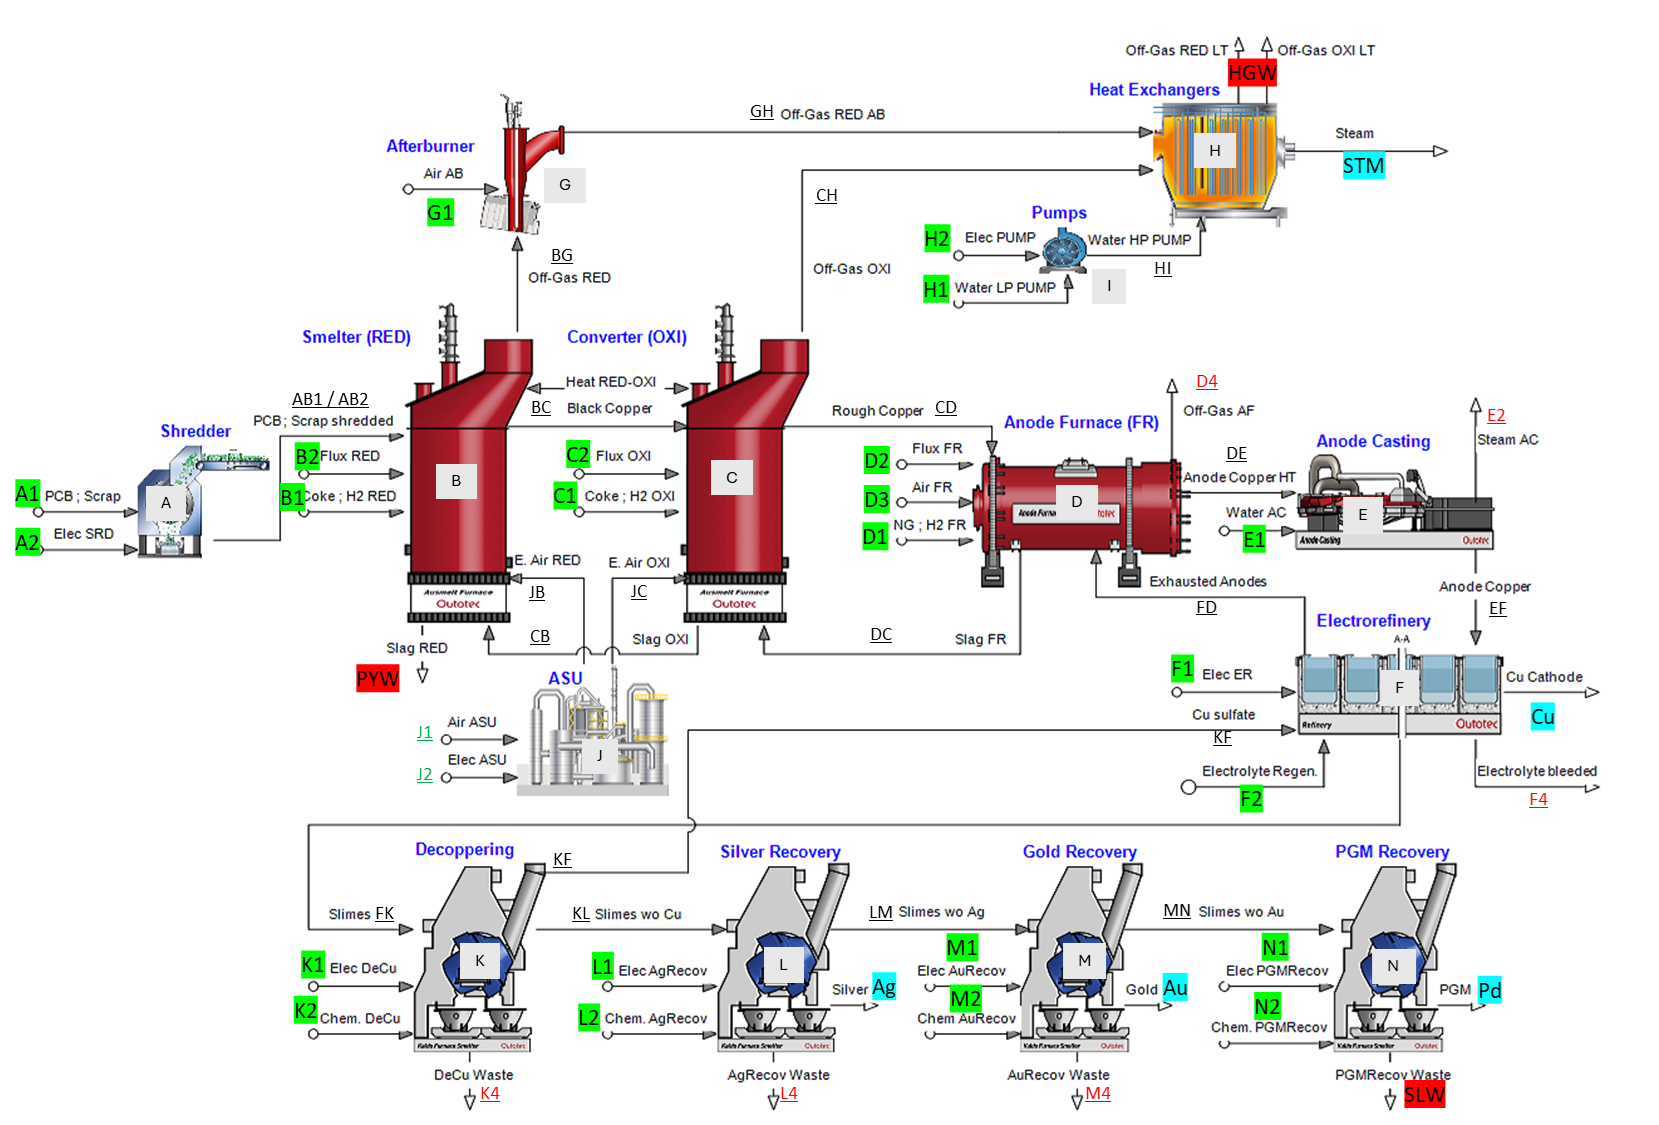

### Read the thermoeconomic model

Select the exergy State `ELC20` to compute generalized cost and summarize using `Resources`

model = ThermoeconomicModel('pcb_model.json',...
    'State','ELC20','CostTables','GENERALIZED','Summary','RESOURCES',...
    'DiagnosisMethod','NONE','Debug',false);
showProperties(model);

 
              State: 'ELC20'
     ReferenceState: 'B20'
     ResourceSample: 'Total'
         CostTables: 'GENERALIZED'
    DiagnosisMethod: 'NONE'
        ActiveWaste: 'PYW'
            Summary: 'RESOURCES'
          Recycling: 'false'
              Debug: 'false'
     IsResourceCost: 'true'
        IsDiagnosis: 'false'
          IsSummary: 'true'
            IsWaste: 'true'



#### Show thermoeconomic Cost for case (ELC20/Total) correspoding to the total generalized cost

ta=model.thermoeconomicAnalysis;
printResults(ta);


Process Generalized Cost - [ELC20/Total]

Key          CP(kW)     CPin(kW)      CPz(kW)     CPex(kW)       CF(kW)       CR(kW)        Z(kW)
——————————————————————————————————————————————————————————————————————————————————————————————————
EDST        12444.0      12444.0          0.0          0.0      12444.0          0.0          0.0
SRD          3946.0       1821.8          0.0       2124.2       1821.8       2124.2          0.0
RED         18900.1      16761.6          0.0       2138.5      18895.7          4.4          0.0
OXI         31387.6      29223.4          0.0       2164.2      31306.6         81.0          0.0
FR          44689.5      42212.4          0.0       2477.2      44689.5          0.0          0.0
AC          44689.5      42212.4          0.0       2477.2      44689.5          0.0          0.0
ER          41876.6      39722.3          0.0       2154.3      41876.6          0.0          0.0
AB           1854.5       1820.6          0.0         34.0       1854.5   

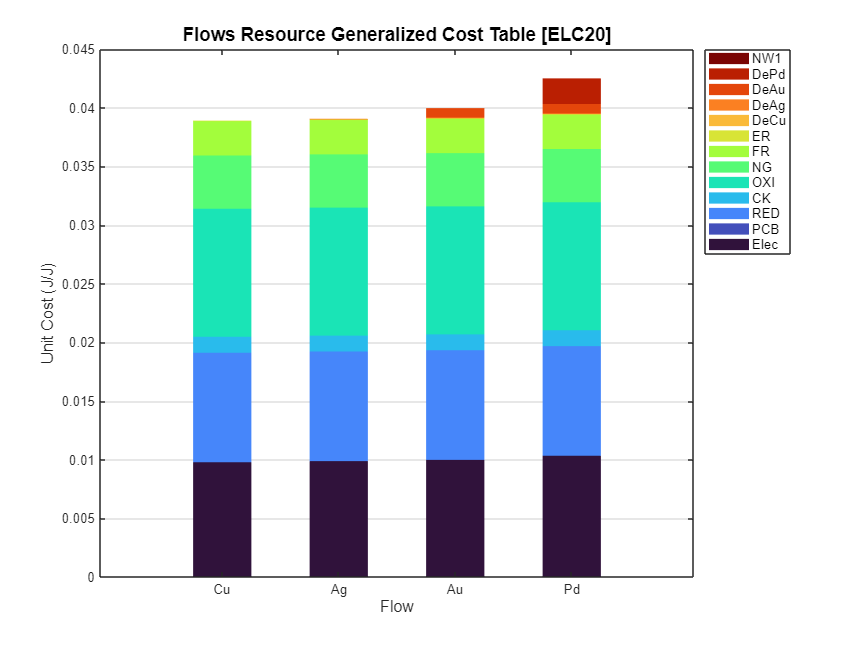

vars={'Cu','Ag','Au','Pd'};
ShowGraph(ta,'Graph','gfrsc','Variables',vars);

#### **Show the Resource Distribution Cost in the case of one of the final product (**`Au)`

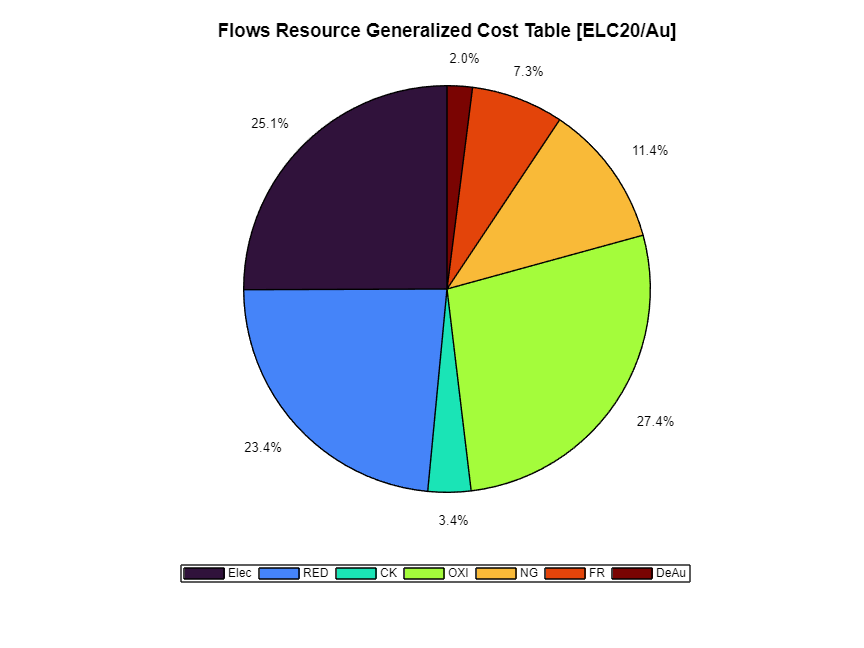

ShowGraph(ta,'Graph','gfrsc','Variables','Au');

#### Show Generalized Unit Cost decomposed by resources

sm=model.summaryResults;
printResults(sm);


Processes Generalized Cost (kW) - [ELC20/SUMMARY]

 key           Total     Mineral          NG         OIL        Coal     Elec_NR      Elec_R
—————————————————————————————————————————————————————————————————————————————————————————————
 EDST        12444.0         0.0         0.0         0.0         0.0     10732.1      1711.9
 SRD          3946.0         7.9       296.1        39.0       413.4      2750.8       438.8
 RED         18900.1       216.5      1210.6      1166.5      4820.5      9905.9      1580.1
 OXI         31387.6       433.3      2169.0      2015.6     11582.7     13097.7      2089.3
 FR          44689.5       564.2      8114.9      2577.1     14937.6     15951.2      2544.4
 AC          44689.5       564.2      8114.9      2577.1     14937.6     15951.2      2544.4
 ER          41876.6       490.7      7057.3      2280.5     12990.7     16435.7      2621.7
 AB           1854.5         0.1         4.7         0.6         6.6      1589.0       253.5
 HE           212

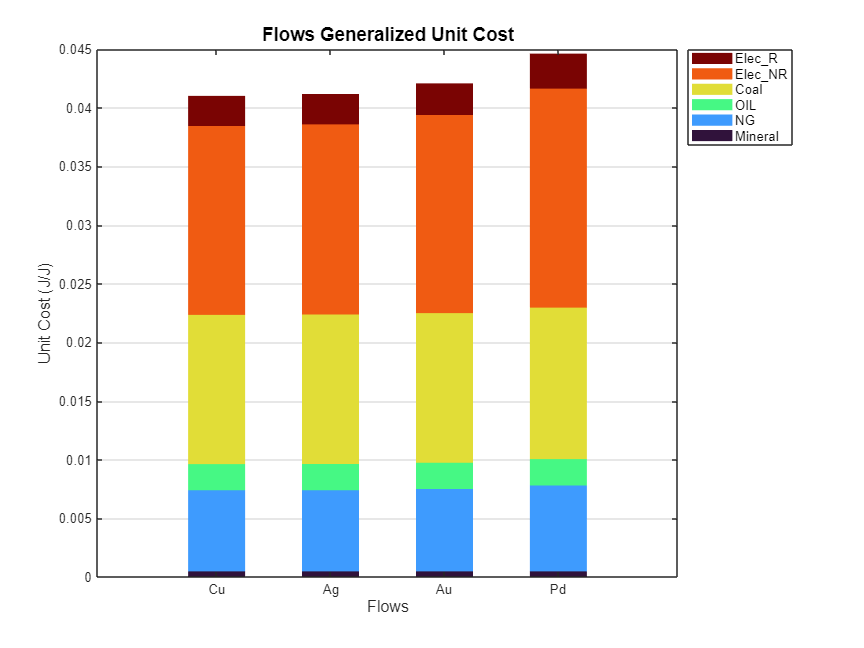

ShowGraph(sm,'Graph','rgfuc','Variables',vars,'Style','Stack')